### **Communication Systems Laboratory**

**Lab 4: OFDM Transmission Using USRP**

**Students: **B11901006 臧逸新、B11901013 俞柏安、B11901101 謝函蓁

#### Wifi-Modulation Initialize

clc; clear; close all;
% Required Files:


%---------Re-generate signal option------%
% 0 for using stored signal 
% 1 for regenerating signal (using usrp)
MULTI_FRAME_SINGLE_DISTANCE_TXRX = 1;
MULTI_FRAME_MULTI_DISTANCE_TXRX  = 1;
%----------------------------------------%
global pilot_idx;
global data_idx;
global zero_idx;
global channel_est
global N_FFT;
global N_CP;
global fs;
global ts;
global fc;
%% Parameters
N_FFT = 64;  % FFT size
N_CP = 16;   % Cyclic prefix length
N_OFDM = N_FFT+N_CP; 
fs = 10e6;   % Sampling rate (Hz)
ts = 1/fs;   % Sampling time
fc = 915e6;  % Carrier frequency (Hz)


% Define subcarrier indices for 802.11a/g
pilot_idx = [12 26 40 54];   % Pilot subcarriers (1-based index)
data_idx = setdiff(1:N_FFT, [1:6, pilot_idx, N_FFT/2+1, 1:6, 60:64]); % Exclude DC, pilot, and unused guard bands
zero_idx = [1:6, N_FFT/2+1, 60:64];

% 5- OFDM symbols with STS, LTS;
% L_sig_5_head = 320;
% L_sig_5 =  L_sig_5_head + 5 * (N_OFDM);
% L_sig_100   = L_sig_5_head + 100 * (N_OFDM);
L_head = 320;
L_sig_100 = L_head + 100*N_OFDM;

% scaling of transmitted amplitude
send_amp = 0.1;

% color style
% '#003C76': Deep Blue
% '#939880': Tea Green
% '#875B75': Plum Purple
% '#DAC1AE': Skin Pink
% '#99755A': Brown
% '#393939': Black
save init.mat pilot_idx data_idx zero_idx ...
            channel_est N_FFT N_CP N_OFDM fs ts fc send_amp...
            L_sig_100 L_head ...
            MULTI_FRAME_SINGLE_DISTANCE_TXRX ...
            MULTI_FRAME_MULTI_DISTANCE_TXRX 

#### **Funcion Definition**

% initialize USRP receiver and transmitter
    
function radio_xx = USRP_init(rx_length, address, whichx)
    %TX_RX_INIT Summary of this function goes here
    %   Detailed explanation goes here
    platform = "N200/N210/USRP2";
    % address  = '192.168.10.2';
    USRPGain            = 5;  % Set USRP radio gain
    USRPCenterFrequency = 915*1e6;  % Set USRP radio center frequency
    
    if whichx == "tx"
        radio_xx = comm.SDRuTransmitter(...
                            'Platform',             platform, ...
                            'IPAddress',            address, ...
                            'CenterFrequency',      USRPCenterFrequency, ...
                            'Gain',                 USRPGain);
    elseif whichx == "rx"
        radio_xx = comm.SDRuReceiver(...
                        'Platform',             platform, ...
                        'IPAddress',            address, ...
                        'CenterFrequency',      USRPCenterFrequency, ...
                        'Gain',                 5, ...
                        'SamplesPerFrame',      rx_length, ...
                        'OutputDataType',       'double') ;
    end
                   
end

% generate single OFDM symbol
function [ofdm_SYM, bit_golden] = ofdm_generate(mod_size)
    %% Generate pilot tones (BPSK modulation)
    global pilot_idx;
    global data_idx;
    global N_FFT

    pilot_bits = [1, 1, 1, -1];
    X_pilot = pilot_bits + 0j; % Convert to complex symbols
    
    %% Generate data tones (16-QAM modulation)
    data_bits   = randi([0 mod_size - 1], length(data_idx), 1); % Random 16-QAM symbols
    bit_golden  = int2bit(data_bits, log2(mod_size)); 
    qam_mod     = qammod(data_bits, mod_size, 'UnitAveragePower', true);

    %% Create OFDM symbol in frequency domain
    ofdm_SYM            = zeros(N_FFT, 1);
    ofdm_SYM(data_idx)  = qam_mod;  % Assign 4-QAM data
    ofdm_SYM(pilot_idx) = X_pilot; % Assign BPSK pilot tones
end

% add time-domain cyclic prefix for a single symbol
function sig_b = ofdm_addCP(sig_a)
    global N_FFT; global N_CP;
    sig_b = zeros(N_FFT + N_CP, 1);
    cyclic_prefix = sig_a(N_FFT-N_CP+1:end);
    sig_b(1:N_CP) = cyclic_prefix;
    sig_b(N_CP+1:end) = sig_a;
end

% remove time-domain cyclic prefix for a single symbol
function sig_c = ofdm_removeCP(sig_b)
    global N_CP;
    sig_c = sig_b(N_CP+1:end);
end

% generate a complete normalized STS 
function [STS, single_STS] = STS_generate()
    global N_FFT;
    STS_values = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, ...
                                0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 0, 0, 0, 0, ...
                                -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
                               0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    
    single_STS = zeros(N_FFT, 1);
    single_STS(7:59) = STS_values;
    
    x_single_sts = ifft(ifftshift(single_STS));
    
    STS = zeros(length(x_single_sts)*2.5, 1);
    STS(1:N_FFT/2) = x_single_sts(N_FFT/2+1:end);
    for i = 0:1
        STS(i*length(x_single_sts)+ N_FFT/2+1 : (i+1)*length(x_single_sts)+ N_FFT/2) = x_single_sts;
    end
    single_STS = STS(1:16);
    STS = STS / mean(abs(STS));
end

% generate a complete normalized LTS
function [LTS, single_LTS] = LTS_generate()
    global N_FFT;
    LTS_values = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];
    
    single_LTS = zeros(N_FFT, 1);
    single_LTS(7:59) = LTS_values;
    
    x_single_lts = ifft(ifftshift(single_LTS)); % time domain

    LTS = zeros(length(x_single_lts)*2.5, 1);
    LTS(1:N_FFT/2) = x_single_lts(N_FFT/2+1:end);
    for i = 0:1
        LTS(i*length(x_single_lts)+ N_FFT/2 +1 : (i+1)*length(x_single_lts)+ N_FFT/2 ) = x_single_lts;
    end
    single_LTS = LTS(end-N_FFT+1:end);
    LTS = LTS / mean(abs(LTS));
end

% fast trim (may not be correct but faster)
function [sec_beg, sec_end] = fast_trim(buffer, plot_len, sec_blank)
    crt = 0.01;
    sec_beg = sec_blank;
    for ii = 1:length(buffer)
        if buffer(ii)>crt
            sec_beg = ii;
            break
        end
    end
    sec_beg = sec_beg - sec_blank + 1;
    sec_end = sec_beg + plot_len + 2*sec_blank;
end

% find starts
function [sts_start, lts_start, ofdm_start] = find_starts(buffer_trimmed, sec_beg, single_LTS)
    conv_sig_LTS = conv(buffer_trimmed, flipud(conj(single_LTS)), "valid"); % index range should be adjusted
    crit_lts = max(abs(conv_sig_LTS))-0.15;
    
    lts_peaks = find(abs(conv_sig_LTS) >= crit_lts);
    lts_start = sec_beg + lts_peaks(1)-1;
    ofdm_start = lts_start + 2*64;
    sts_start = lts_start - 32 - 160;
end

% Channel estimation using LTS
function H_est = channel_est_LTS(buffer_trimmed, lts_start)
    LTS_val = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1];
    lts_1       = buffer_trimmed(lts_start : lts_start+64-1);
    LTS_1_RX    = fftshift(fft(lts_1));
    H1          = zeros(64, 1);
    est_idx     = (-26+33: 26+33); % -26 to 26 except '0'
    H1(est_idx) = LTS_1_RX(est_idx).*LTS_val.';
    H_est       = H1;
end

% Equalization
function  [Pilot, Data] = Equalize(Symbol, H) % freq domain
    global data_idx;
    global pilot_idx;
    Y = Symbol;

    Data = zeros(48, 1);
    Pilot = zeros(4, 1);

    data_nonzero_idx = data_idx(H(data_idx) ~= 0);

    Data = Y(data_idx)./H(data_idx);
    Pilot = Y(pilot_idx)./H(pilot_idx);
end

**[Part 1] Cross-USRP Wi-Fi-Based OFDM transmission (60 points)**

**Network Configuration**

**(1) **Describe your network configuration that allows the computer to control two USRPs. More specifically, please describe the network configuration at your computer (IP & subnet mask) and the IP addresses you assign for the two USRPs.

**Ans:**

USRP 1:

IP address = 192.168.10.1

Subnet mask = 255.255.255.0

Default gateway = 192.168.10.2

USRP 2:

IP address = 192.168.20.1

Subnet mask = 255.255.255.0

Default gateway = 192.168.20.2

**(2)** Explain how the above network configuration allows you to control two USRPs from your computer.

**Ans:**

Default gateway is set to the USRP's IP setup.

For each USRP, since subnet mask is set to 24 bits, the host ID (the first 24 bits, i.e. the first three sections) of the NIC's IP address are set to the same as the default gateway so that they are in the same subnet. The network ID (the last 8 bits, i.e. the last section) is set differently so that they are separate identities within their subnet.

The two USRP's NIC's IP address are set differently so that the computer can identify them.

When we execute "findsdru()", matlab scan through all NIC on the computer and successfully communicate with the USRPs through those NICs.

**Resolve Cross-Device Synchronization Issues**

Transmit a frame with 100 OFDM data symbols with 4-QAM modulation using USRP 1. Receive the frame with USRP 2. Develop a strategy that allows complete capture of a whole frame at USRP 2.

For example, you can try:

`•` Append/prepend zeros to the transmit frame to make the beginning and the end of the frame visually apparent.

`•` Capture a longer range in the time domain than the transmitted frame.

`•` Retransmission scheme with ACK/NAK from USRP 2.

`•` ...

**(3) **Explain the strategy you employ to ensure complete capture of a whole frame at USRP 2.

**Our strategy:**

Sequenced by time, this is what we do when USRP is on:

1st frame: send zeros, receive

2nd frame: send the generated frame (padded with 100 zeros), receive

3rd frame: send nothing, keep receiving

**Explanation:**

We send zeros first in case USRP refuse to receive at the first few samples.

The generated frame is guarded by 100 zeros at the start and the end. It's just a simple protection.

We keep receive after the frame is sent in case there are some delay between sending and receiving.

The time of protection operations is minimized with tests.

**(4) **Using the above proposed strategy, plot the received signal in the time domain at USRP 2. Mark the beginning and the end of the frame to show a successful capture of a whole frame.

**Generate a 100-symbol frame**

clc; clear; close all;
load("init.mat")

L_head = 320;
L_sig_100 = L_head + 100*N_OFDM;

sig_100 = zeros(L_sig_100, 1);
data_tx = zeros(5*48, 1);

% generate frame head
[STS, single_STS] = STS_generate();
[LTS, single_LTS] = LTS_generate();
sig_100(1:length(STS)) = STS;
sig_100(length(STS)+1:length(STS)+length(LTS))= LTS;

% generate 100 OFDM Symbols
for i = 0:(100-1)
    x_fft = ofdm_generate(4); % one OFDM symbol, 4-qam
    x = ifft(ifftshift(x_fft));
    x_cp = ofdm_addCP(x);
    sig_100(L_head + i*(N_OFDM)+1 : L_head+(i+1)*(N_OFDM)) = x_cp;
    
    data_tx(48*i+1 : 48*(i+1)) = x(data_idx);
end
sig_100(L_head+1:end) = sig_100(L_head+1:end)/mean(abs(sig_100(L_head+1:end)));

bits_tx = qamdemod(data_tx, 4, 'gray', OutputType='bit', UnitAveragePower=true);
padded_sig_100 = send_amp*[zeros(100, 1); sig_100; zeros(100, 1)];
save sig_100_send.mat sig_100 STS LTS

**Send the frame**

l = length(padded_sig_100);
radio_Tx = USRP_init(l, '192.168.10.2', "tx");
radio_Rx = USRP_init(l, '192.168.20.2', "rx");
buffer = zeros(5*l, 1);

% Transmit the frame we generate

for ii = 1:3
    if ii == 2
        tunderrun = radio_Tx(padded_sig_100);
    else
        tunderrun = radio_Tx(complex(zeros(l, 1)));
    end
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
end
% Keep reception for 2 frames
for ii = 4:5
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
end 

release(radio_Tx)
release(radio_Rx)


**Trim and plot**

[sec_beg, sec_end] = fast_trim(buffer, 8500, 100);

single_LTS = LTS(end-64+1:end);
[sts_start, lts_start, ofdm_start] = find_starts(buffer(sec_beg:sec_end), sec_beg, single_LTS)

% plot the location of estimated starts
figure;
time_vector = (sec_beg:sec_end);
plot(time_vector, real(buffer(sec_beg:sec_end)), 'Color', '#003C76');
hold on
xline(sts_start, 'Color', '#393939','LineWidth', 1);
xline(lts_start, 'Color', '#939880','LineWidth', 1);
xline(ofdm_start, 'Color', '#875B75','LineWidth', 1);
xline(sts_start + L_sig_100, 'Color', '#DAC1AE','LineWidth', 1);
hold off
xlim([sec_beg sec_end])
xt = xticks;
xticklabels(xt * ts*1e6);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('4. Time-Domain received signal (real)');
legend('received signal','sts\_start', 'lts\_start', 'ofdm\_start', 'frame\_end')

save sig_100_recv.mat buffer sts_start lts_start ofdm_start

**(5) **Without CFO correction, plot the received constellation (only the data tones). Do you observe the constellation rotating?

**Ans:**

Yes, severe rotation.

clc; clear;
load("init.mat")
load("sig_100_recv.mat")

ofdm_rx_CP = reshape(...
    buffer(ofdm_start:(ofdm_start+(N_FFT+N_CP)*100-1)),...
    [], 100);

ofdm_rx = zeros(N_FFT, 100);
ofdm_rx_sym = zeros(N_FFT, 100);
for ii = 1:100
    ofdm_rx(:,ii) = ofdm_removeCP(ofdm_rx_CP(:, ii));
    ofdm_rx_sym(:, ii) = fftshift(fft(ofdm_rx(:, ii)));
end

% ideal symbols
M = 4;  % 4-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data
figure;
plot(reshape(ofdm_rx_sym(data_idx, :)/ mean(mean(abs(ofdm_rx_sym))), 1, []),...
    'o','Color', '#875B75', 'MarkerFaceColor', '#875B75', 'MarkerSize', 1.5);
hold on;

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'Color', '#393939','LineWidth', 1);
yline(0, 'Color', '#393939','LineWidth', 1);
legend('received data', 'ideal consellation')
title("5. Constellation before equalize")

axis square;
grid on;
hold off;

**(6)** Estimate the CFO of the received frame. What is the estimated CFO? Also, please explain your CFO estimation process. For instance, whether the CFO is estimated from STS, LTS, or both.

**Ans:** Our CFO estimation is from the two LTS.

%clear; clc;
load('sig_100_recv.mat');
lts_start_1 = lts_start;
lts_start_2 = lts_start_1 + 64;
lts_1 = buffer(lts_start_1:lts_start_1 + 64-1);
lts_2 = buffer(lts_start_2:lts_start_2 + 64-1);

phase_diff = angle(sum(lts_2 .* conj(lts_1)));
cfo_hz = phase_diff / (2*pi*64*ts);  % 64 is time diff between 8th and 10th

cfo_ppm = cfo_hz / fc * 1e6;

fprintf("CFO estimated by consecutive LTS(PPM) = %.2f", cfo_ppm);



**(7)** Apply CFO correction to the received frame and then estimate the channel. Plot (i) the magnitude and (ii) the phase of the estimated channel vs subcarrier, with zero subcarrier in the middle. Describe and discuss the figure.

function sig_CFO_corrected = CFO_correction(sig, L, cfo_ppm)
    global ts;
    global fc;
    global fs;

    delta_f= fc*cfo_ppm/1e6;
    
    t = (0:L-1) * ts;
    idx = exp(-1j*2*pi* delta_f .*t);
    sig_CFO_corrected = sig .* idx(:);
end

[sec_beg, sec_end] = fast_trim(buffer, 8500, 100);
sig_CFO_corrected = CFO_correction(buffer(sec_beg:sec_end), sec_end-sec_beg+1, cfo_ppm);


H1 = channel_est_LTS(sig_CFO_corrected, lts_start-sec_beg+1);
H2 = channel_est_LTS(sig_CFO_corrected, lts_start-sec_beg+1+64);

% plot magnitude
freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64);
close all;
figure(2); hold on;
s1 = stem(freq_vector/1e6, abs(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, abs(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 1]);
legend([s1(1), s2(1)],'H1', 'H2');
title('5. Channel Estimation after CFO correction (Magnitude)');
grid on;
hold off;

% plot phase
figure(3);
s1 = stem(freq_vector/1e6, angle(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, angle(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
axis([910 920 -4 4])
legend([s1(1), s2(1)],'H\_1', 'H\_2');
title('5. Channel Estimation after CFO correction (Phase)');
grid on;
hold off;

**Discussion:**

**(8) **Perform equalization on the received frame. Plot the CFO-corrected and equalized received constellation (only the data tones). Do you still observe the constellation rotating?

num_of_symbol = 100;
H_est = (H1+H2)/2;
Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);

P_OFDM = mean(abs (sig_CFO_corrected(ofdm_start-sec_beg+1:ofdm_start + 80*num_of_symbol-1 -sec_beg+1) ) );
for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(sig_CFO_corrected(ofdm_start + ii*(N_FFT+N_CP) -sec_beg+1: ofdm_start-1 + (ii+1)*(N_FFT+N_CP) -sec_beg+1));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;
    Data_rx(48*ii+1 : 48*(ii+1)) = Data;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end


I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 4;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
close all;
figure(1);
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('8. Received Constellation with CFO corrected');

axis equal;
grid on;
hold off;

**Observation: **Sometimes there's still large rotation remaining while sometimes no. Usually when the antennas are parallel, there's no rotating, while severe rotating may happen if the two antennas are perpendicular

**(9)** Use the four pilot tones to track the residual CFO and further correct the data tones accordingly. With the assistance of the pilot tones, plot the received constellation (only the data tones). What do you observe?

% calculate residual CFO phase　(beta) for one OFDM symbol
function res_CFO_phase = Res_CFO_calc(Pilots, Q)
    res_CFO_phase = angle(sum(Pilots .* conj(Q)));
end

% perform residual CFO correction for one OFDM symbol
function Data_res_CFO_corrected = Res_CFO_correction(Data, res_CFO_phase)
    Data_res_CFO_corrected = Data*exp(-1j*res_CFO_phase);
end

signal_rx = sig_CFO_corrected;
Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);


for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(signal_rx(ofdm_start + ii*(N_FFT+N_CP) -sec_beg+1: ofdm_start-1 + (ii+1)*(N_FFT+N_CP) -sec_beg+1));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;

    % Q = H_est(pilot_idx); % done by LTS
    Q = [1; 1; 1; 1];
    res_CFO_phase = Res_CFO_calc(Pilot, Q);
    Data_res_CFO_corrected = Res_CFO_correction(Data, res_CFO_phase);
    Data_rx(48*ii+1 : 48*(ii+1)) = Data_res_CFO_corrected;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end

Data_rx = Data_rx / mean(abs(Data_rx));
I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 4;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
close all;
figure(1);
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('9. Received Constellation with residual CFO corrected');

axis equal;
grid on;
hold off;

**(10)** Demodulate the received signal at USRP 2 and calculate the bit error rate for this single frame. What is the BER? The goal is to obtain no (or very few) bit errors.

M = 4;
load("sig_100_send.mat");
Data_tx = zeros(48*num_of_symbol, 1);
for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    
    sig_c = ofdm_removeCP(sig_100(321 + ii*(N_FFT+N_CP): 321-1 + (ii+1)*(N_FFT+N_CP)));
    X_tx = fftshift(fft(sig_c));
    Data = X_tx(data_idx).';
    Data_tx(48*ii+1 : 48*(ii+1)) = Data;
end
data_tx_bits = qamdemod(Data_tx, M, 'gray', 'UnitAveragePower', true, OutputType="bit");
data_rx_bits = qamdemod(Data_rx, M, 'gray', 'UnitAveragePower', true, OutputType="bit");
numErrors = sum(data_tx_bits~=data_rx_bits);
BER_single_frame = (numErrors/length(data_tx_bits))

**(11)** Change the modulation to 16-QAM and repeat the experiment. Plot the CFO corrected, equalized, and pilot-assisted constellations as in (9).

clc; clear; close all;
load("init.mat")


L_head = 320;
L_sig_100 = L_head + 100*N_OFDM;

sig_100 = zeros(L_sig_100, 1);
data_tx = zeros(5*48, 1);

% generate frame head
[STS, single_STS] = STS_generate();
[LTS, single_LTS] = LTS_generate();
sig_100(1:length(STS)) = STS;
sig_100(length(STS)+1:length(STS)+length(LTS))= LTS;

% generate 100 OFDM Symbols
for i = 0:(100-1)
    x_fft = ofdm_generate(16); % one OFDM symbol, 4-qam
    x = ifft(ifftshift(x_fft));
    x_cp = ofdm_addCP(x);
    sig_100(L_head + i*(N_OFDM)+1 : L_head+(i+1)*(N_OFDM)) = x_cp;
    
    data_tx(48*i+1 : 48*(i+1)) = x(data_idx);
end
sig_100(L_head+1:end) = sig_100(L_head+1:end)/mean(abs(sig_100(L_head+1:end)));

bits_tx = qamdemod(data_tx, 16, 'gray', OutputType='bit', UnitAveragePower=true);
padded_sig_100 = send_amp*[zeros(100, 1); sig_100; zeros(100, 1)];
%save sig_100_16_send.mat sig_100 bits_tx



l = length(padded_sig_100);

Unrecognized function or variable 'padded_sig_100'.

radio_Tx = USRP_init(l, '192.168.10.2', "tx");
radio_Rx = USRP_init(l, '192.168.20.2', "rx");
buffer = zeros(5*l, 1);

% Transmit the frame we generate

for ii = 1:3
    if ii == 2
        tunderrun = radio_Tx(padded_sig_100);
    else
        tunderrun = radio_Tx(complex(zeros(l, 1)));
    end
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
end
% Keep reception for 2 frames
for ii = 4:5
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
end 

release(radio_Tx)
release(radio_Rx)

Don't run if you executed the USRP block

load("sig_100_16_recv.mat")
load("sig_100_16_send.mat")

[sec_beg, sec_end] = fast_trim(buffer, 8500, 100);

single_LTS = LTS(end-64+1:end);
[sts_start, lts_start, ofdm_start] = find_starts(buffer(sec_beg:sec_end), sec_beg, single_LTS)

sts_start = 9121

lts_start = 9313

ofdm_start = 9441

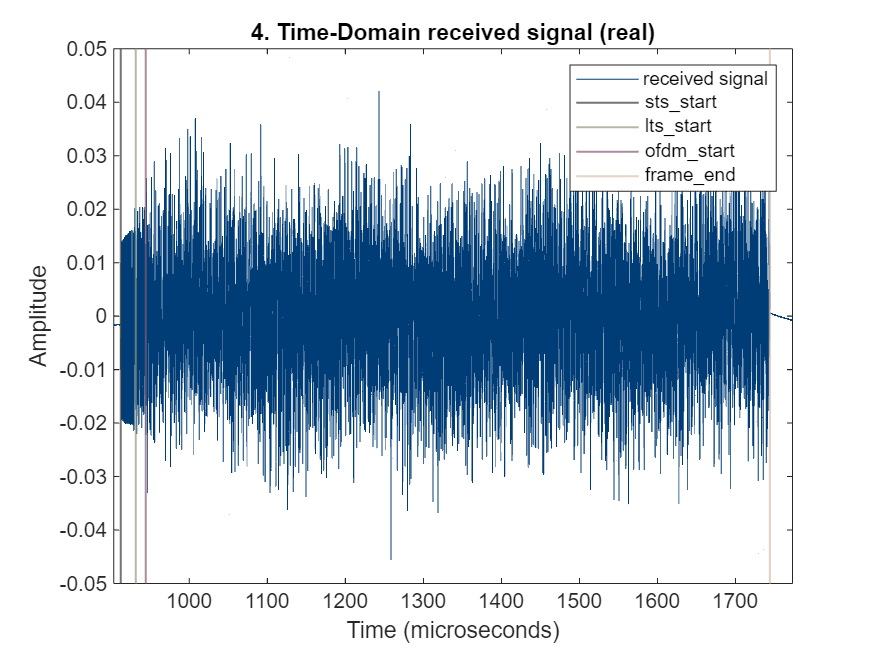


% plot the location of estimated starts
figure;
time_vector = (sec_beg:sec_end);
plot(time_vector, real(buffer(sec_beg:sec_end)), 'Color', '#003C76');
hold on
xline(sts_start, 'Color', '#393939','LineWidth', 1);
xline(lts_start, 'Color', '#939880','LineWidth', 1);
xline(ofdm_start, 'Color', '#875B75','LineWidth', 1);
xline(sts_start + L_sig_100, 'Color', '#DAC1AE','LineWidth', 1);
hold off
xlim([sec_beg sec_end])
xt = xticks;
xticklabels(xt * ts*1e6);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('4. Time-Domain received signal (real)');
legend('received signal','sts\_start', 'lts\_start', 'ofdm\_start', 'frame\_end')


%save sig_100_16_recv.mat buffer sts_start lts_start ofdm_start


Plot before correction for reference

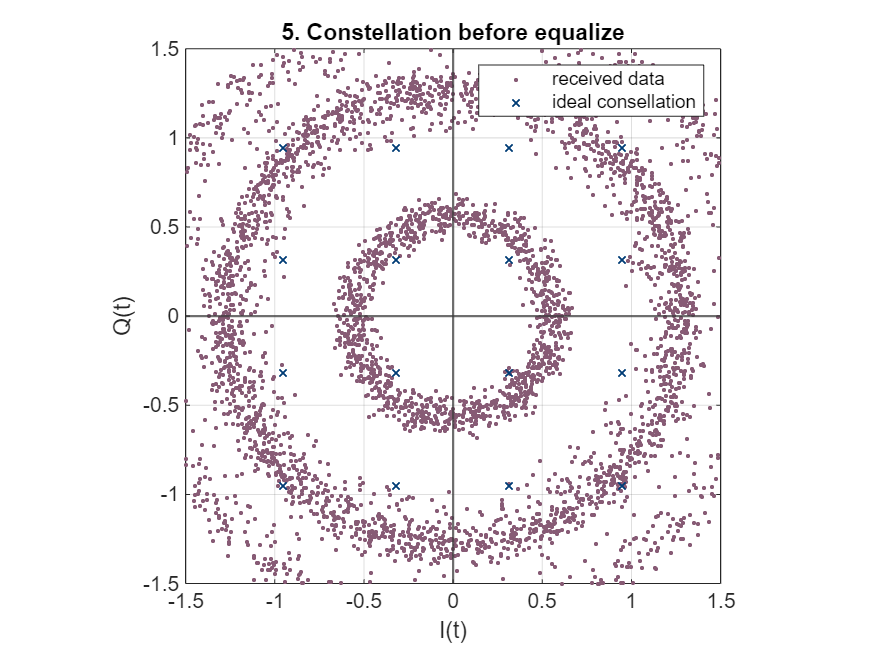

ofdm_rx_CP = reshape(...
    buffer(ofdm_start:(ofdm_start+(N_FFT+N_CP)*100-1)),...
    [], 100);

ofdm_rx = zeros(N_FFT, 100);
ofdm_rx_sym = zeros(N_FFT, 100);
for ii = 1:100
    ofdm_rx(:,ii) = ofdm_removeCP(ofdm_rx_CP(:, ii));
    ofdm_rx_sym(:, ii) = fftshift(fft(ofdm_rx(:, ii)));
end

% ideal symbols
M = 16;  % 4-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data
figure;
plot(reshape(ofdm_rx_sym(data_idx, :)/ mean(mean(abs(ofdm_rx_sym))), 1, []),...
    'o','Color', '#875B75', 'MarkerFaceColor', '#875B75', 'MarkerSize', 1.5);
hold on;

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'Color', '#393939','LineWidth', 1);
yline(0, 'Color', '#393939','LineWidth', 1);
legend('received data', 'ideal consellation')
title("5. Constellation before equalize")

axis square;
grid on;
hold off;

lts_start_1 = lts_start;
lts_start_2 = lts_start_1 + 64;
lts_1 = buffer(lts_start_1:lts_start_1 + 64-1);
lts_2 = buffer(lts_start_2:lts_start_2 + 64-1);

phase_diff = angle(sum(lts_2 .* conj(lts_1)));
cfo_hz = phase_diff / (2*pi*64*ts);  % 64 is time diff between 8th and 10th

cfo_ppm = cfo_hz / fc * 1e6;

fprintf("CFO estimated by consecutive LTS(PPM) = %.2f", cfo_ppm);

CFO estimated by consecutive LTS(PPM) = 4.89

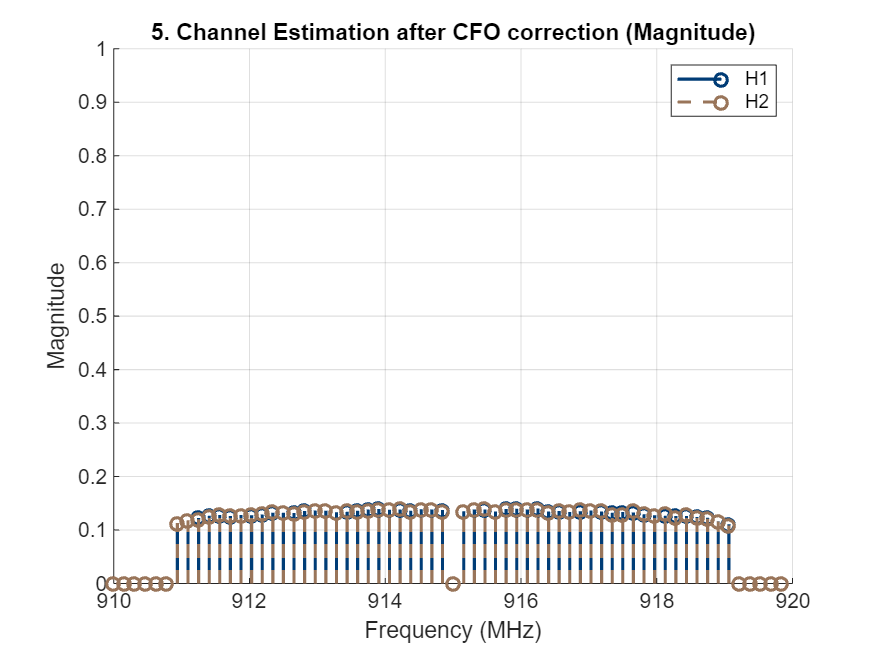

sig_CFO_corrected = CFO_correction(buffer(sec_beg:sec_end), sec_end-sec_beg+1, cfo_ppm);


H1 = channel_est_LTS(sig_CFO_corrected, lts_start-sec_beg+1);
H2 = channel_est_LTS(sig_CFO_corrected, lts_start-sec_beg+1+64);

% plot magnitude
freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64);
close all;
figure(2); hold on;
s1 = stem(freq_vector/1e6, abs(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, abs(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 1]);
legend([s1(1), s2(1)],'H1', 'H2');
title('5. Channel Estimation after CFO correction (Magnitude)');
grid on;
hold off;

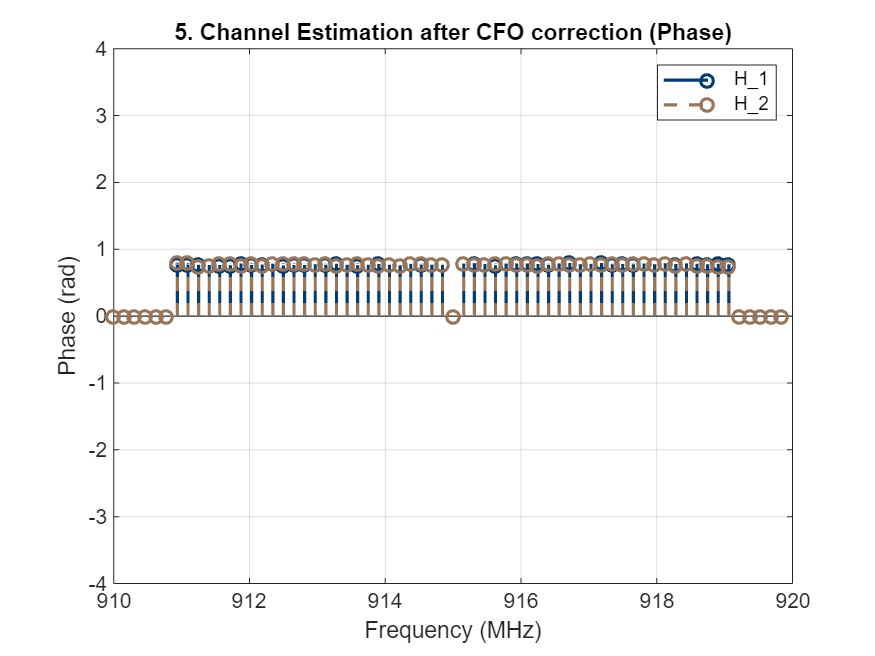


% plot phase
figure(3);
s1 = stem(freq_vector/1e6, angle(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, angle(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
axis([910 920 -4 4])
legend([s1(1), s2(1)],'H\_1', 'H\_2');
title('5. Channel Estimation after CFO correction (Phase)');
grid on;
hold off;

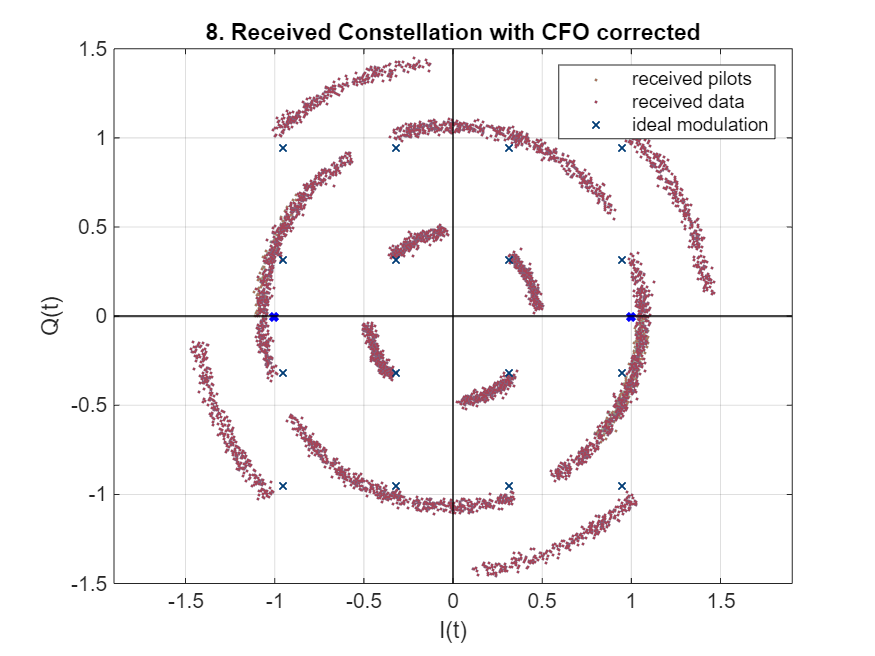

num_of_symbol = 100;
H_est = (H1+H2)/2;
Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);

P_OFDM = mean(abs (sig_CFO_corrected(ofdm_start-sec_beg+1:ofdm_start + 80*num_of_symbol-1 -sec_beg+1) ) );
for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(sig_CFO_corrected(ofdm_start + ii*(N_FFT+N_CP) -sec_beg+1: ofdm_start-1 + (ii+1)*(N_FFT+N_CP) -sec_beg+1));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;
    Data_rx(48*ii+1 : 48*(ii+1)) = Data;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end


I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 16;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
close all;
figure(1);
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('8. Received Constellation with CFO corrected');

axis equal;
grid on;
hold off;

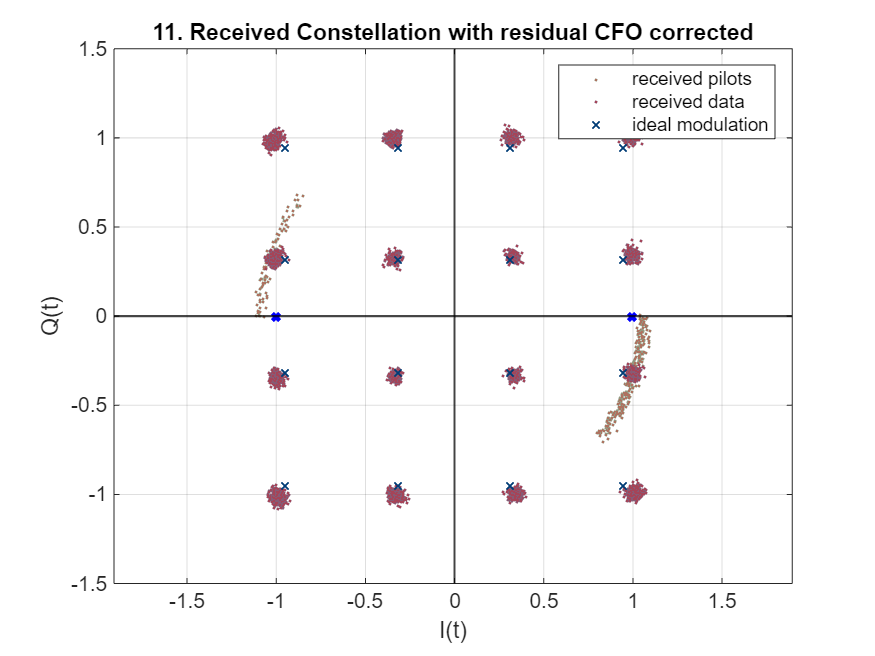

signal_rx = sig_CFO_corrected;
Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);


for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(signal_rx(ofdm_start + ii*(N_FFT+N_CP) -sec_beg+1: ofdm_start-1 + (ii+1)*(N_FFT+N_CP) -sec_beg+1));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;

    % Q = H_est(pilot_idx); % done by LTS
    Q = [1; 1; 1; 1];
    res_CFO_phase = Res_CFO_calc(Pilot, Q);
    Data_res_CFO_corrected = Res_CFO_correction(Data, res_CFO_phase);
    Data_rx(48*ii+1 : 48*(ii+1)) = Data_res_CFO_corrected;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end

Data_rx = Data_rx / mean(abs(Data_rx));
I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 16;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
close all;
figure(1);
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('11. Received Constellation with residual CFO corrected');

axis equal;
grid on;
hold off;

**(12)** Following (11), what is the BER using 16-QAM modulation? How does it compare to the BER using 4-QAM in (10)?

M = 16;
Data_tx = zeros(48*num_of_symbol, 1);
for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    
    sig_c = ofdm_removeCP(sig_100(321 + ii*(N_FFT+N_CP): 321-1 + (ii+1)*(N_FFT+N_CP)));
    X_tx = fftshift(fft(sig_c));
    Data = X_tx(data_idx).';
    Data_tx(48*ii+1 : 48*(ii+1)) = Data;
end
Data_tx = Data_tx / mean(abs(Data_tx));
Data_rx = Data_rx / mean(abs(Data_rx));
data_tx_bits = qamdemod(Data_tx, M, 'gray', 'UnitAveragePower', true, OutputType="bit");
data_rx_bits = qamdemod(Data_rx, M, 'gray', 'UnitAveragePower', true, OutputType="bit");
numErrors = sum(data_tx_bits~=data_rx_bits);
BER_single_frame = (numErrors/length(data_tx_bits))

BER_single_frame = 0

**Establish a Framework to Transmit Multiple Frames**

Expanding your framework to transmit multiple frames, each with different random bits.

**(13) **Transmit and receive 20 frames, each with 100 OFDM symbols using 16-QAM modulation. Calculate the BER for each of the 20 frames. Plot BER per frame vs frame number, and provide the total BER for the 20 frames. The goal is to show that your transmission framework is robust enough that you can consistently collect usable experimental data. Thus, the BER should be rather consistent across different frames.

**Send and receive 20 frames**

clc; clear;
load("init.mat")
load("sig_100_send.mat")

num_symbol  = 100;
num_frame   = 20;
qam_size    = 16;
bit_golden  = zeros([num_symbol*48*log2(qam_size), 1]);
sig_100_new = [STS; LTS];
sym_amp     = 0.005;
for ii = 0:num_symbol-1
    [x_fft, bit_golden(48*log2(qam_size)*ii+1: ...
                       48*log2(qam_size)*(ii+1))] ...
          = ofdm_generate(qam_size);
    x     = ifft(ifftshift(x_fft));
    x_cp  = ofdm_addCP(x);
    sig_100_new = [sig_100_new; x_cp];
end

bit_golden                = repmat(bit_golden, [1, num_frame]);
sig_100_new(L_head+1:end) = sym_amp * ...
sig_100_new(L_head+1:end)/mean(abs(sig_100_new(L_head+1:end)));
padded_sig_100_new        = send_amp*[zeros(100, 1); sig_100_new; zeros(100, 1)];

function buffer_20 = multi_frame_transmission(padded_sig_100_new, num_frame)
    l          = length(padded_sig_100_new);
    buffer_20  = zeros(5*l, num_frame);
    radio_Tx   = USRP_init(l, '192.168.10.2', "tx");
    radio_Rx   = USRP_init(l, '192.168.20.2', "rx");
    for jj = 1:num_frame
        for ii = 1:3
            if ii == 2
                tunderrun = radio_Tx(padded_sig_100_new);
            else
                tunderrun = radio_Tx(complex(zeros(l, 1)));
            end
            [rcvdSignal, ~, toverflow] = step(radio_Rx);
            buffer_20((1+(ii-1)*l):(ii*l), jj) = rcvdSignal;
        end
        % Keep reception for 2 frames
        for ii = 4:5
            [rcvdSignal, ~, toverflow] = step(radio_Rx);
            buffer_20((1+(ii-1)*l):(ii*l), jj) = rcvdSignal;
        end 
    end
    release(radio_Tx)
    release(radio_Rx)
    
end

function [frame_start, frame_end] = get_start(buffer_big, single_STS, L_sig_100)
    temp            = abs(conv(buffer_big, single_STS, "same"));
    potential       = find(temp>0.01);
    frame_start     = potential(1) - 100;
    frame_end       = frame_start + L_sig_100 + 200;                                  % sync-1
end

function [lts_start, ofdm_start, sym_emp] = get_sym_emp(buffer_big_trimmed, ...
    num_symbol, single_LTS, sym_amp)
    global N_FFT;
    global N_CP;
    global data_idx;
    [~, lts_start, ofdm_start] = find_starts(buffer_big_trimmed, 1, single_LTS);      % sync-2
    H_est                   = channel_est_LTS(buffer_big_trimmed, lts_start);         % CE
    sym_in_buffer           = reshape(buffer_big_trimmed(ofdm_start: ...
        (ofdm_start+(N_FFT+N_CP)*num_symbol-1)), [], num_symbol);
    sym_in_buffer           = sym_in_buffer(N_CP+1 : end, :);                         % rm CP
    sym_in_buffer_freq      = fftshift(fft(sym_in_buffer, [], 1), 1);                 % FFT
    sym_emp_single_frame    = sym_in_buffer_freq(data_idx, :) ./ H_est(data_idx, :);  % Equ
    sym_emp                 = reshape(sym_emp_single_frame, [], 1)/sym_amp;
end

if MULTI_FRAME_SINGLE_DISTANCE_TXRX == 0
    load("sig_100_recv_20.mat")
else
    buffer_20 = multi_frame_transmission(padded_sig_100_new, num_frame);
    save("sig_100_recv_20.mat", "buffer_20", "bit_golden")
end

frame_idx   = zeros([2, num_frame]);
sym_emp_all = zeros([48*num_symbol, num_frame]);

for ii = 1:num_frame
    [frame_idx(1,ii), frame_idx(2,ii)] ...
        = get_start(buffer_20(:, ii), single_STS, L_sig_100);
end
for ii = 1:num_frame
    [lts_start, ofdm_start, sym_emp_all(:, ii)] = get_sym_emp( ... 
        buffer_20(frame_idx(1,ii):frame_idx(2,ii), ii), ...
        num_symbol, single_LTS, sym_amp);
end
bit_emp_all = qamdemod(sym_emp_all, qam_size, "gray", ...
    UnitAveragePower=true, OutputType="bit");   % Demod
BER_1       = sum(xor(bit_emp_all, bit_golden))/(48*num_symbol*log2(qam_size));
total_BER   = sum(xor(bit_emp_all, bit_golden), "all")/ ...
    (48*num_frame*num_symbol*log2(qam_size));
fprintf("13. Total BER = %d", total_BER)
stem(BER_1)
title("13. BER per frame vs frame number")
xlabel("frame number")
ylabel("BER (log scale)")

**(14)** Calculate the BER per subcarrier based on the received 20 frames. Plot BER vs subcarrier. Describe and analyze the BER figure you obtain. Is there frequency-dependent BER behavior? If some subcarriers experience higher bit errors, what do you think is the reason?

bit_emp_all = reshape(bit_emp_all, 48, []);
bit_golden  = reshape(bit_golden, 48, []);
BER_2       = sum(xor(bit_emp_all, bit_golden), 2)/(num_frame*num_symbol*log2(qam_size));
stem(data_idx-N_FFT/2-1, fftshift(BER_2))
title("14. BER vs subcarrier")
xlabel("subcarrier")
ylabel("BER (log scale)")

**(15)** Please select three (or more) transmission distances (please measure the distance). At each distance, transmit and receive 20 frames, each with 100 OFDM symbols using 16-QAM modulation as in (13). Plot the total BER vs transmission distance, showing that the BER increases with distance.

dis = [1, 10, 20];
dis_ind = 3; % tune by hand

if MULTI_FRAME_MULTI_DISTANCE_TXRX == 0
    load("sig_100_recv_20.mat")
else
    buffer_20 = multi_frame_transmission(padded_sig_100_new, num_frame);
end

for ii = 1:num_frame
    [frame_idx(1,ii), frame_idx(2,ii)] ...
        = get_start(buffer_20(:, ii), single_STS, L_sig_100);
end
for ii = 1:num_frame
    [lts_start, ofdm_start, sym_emp_all(:, ii)] = get_sym_emp( ... 
        buffer_20(frame_idx(1,ii):frame_idx(2,ii), ii), ...
        num_symbol, single_LTS, sym_amp);
end
bit_golden = reshape(bit_golden, [], num_frame);
bit_emp_all = qamdemod(sym_emp_all, qam_size, "gray", ...
    UnitAveragePower=true, OutputType="bit");   % Demod
BER_dis(dis_ind) = sum(xor(bit_emp_all, bit_golden), "all")/ ...
    (48*num_frame*num_symbol*log2(qam_size));

semilogy(dis, BER_dis, Marker="+")
title("15. BER vs transmission distance")
xlabel("transmission distance (cm)")
ylabel("BER (log scale)")
ylim([1e-2, 0.7])

**[Part 2] Demo (40 points, no report needed)**